# **HW - separate audio mix using ICA**

Load mixed audio (save sample audio into ../data directory)

In this assignment, the number of audio sources is equal to mic (channels)

Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "AAR" v131130 (see >> help eegplugin_aar)
EEGLAB: adding "AMICA" v1.7 (see >> help eegplugin_amica)
EEGLAB: adding "ANTeepimport" v1.14 (see >> help eegplugin_eepimport)
EEGLAB: adding "Adjust" v1.1.1 (see >> help eegplugin_adjust)
EEGLAB: adding "BDFimport" v1.2 (see >> help eegplugin_bdfimport)
EEGLAB: adding "Biosig" v3.8.4 to the path
EEGLAB: adding "EEG-BIDS" v9.1 (see >> help eegplugin_eegbids) - new version 10.1 available
EEGLAB: adding "ICLabel" v1.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "MARA" v1.2 (see >> help eegplugin_MARA)
EEGLAB: adding "bva-io" v1.73 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata) - new version 2.10 available
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit) - new version 5.5 available
EEG

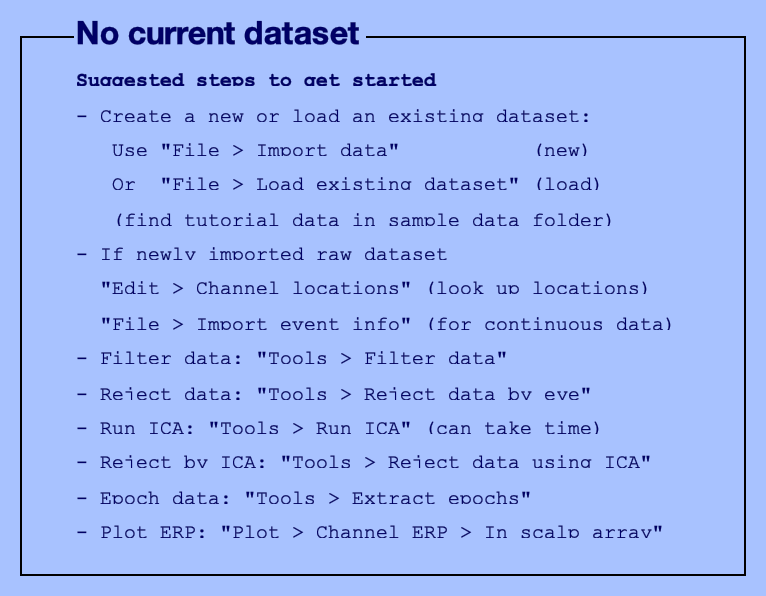

eeglab;

### Goals

- To estimate original audio soures through ICA

- To estimate mixing matrix wegiths (N by N matrix)

- To select corresponding sources that consists of the given audio mix and justify it (based on minimum error, highest correlation, comparing their spectrogram, etc.)

[X, fs] = audioread('../data/mixed_audio_2mix_v2.wav');  % X: (samples x channels)

disp('Mixed audio dimension:');

Mixed audio dimension:


disp(size(X));

    10625664           2



### Play the given audio mix

player = audioplayer(X, fs);
play(player)

### Stop playing

stop(player)

X = X';  % Transpose to (channels x samples)

## Run ICA runica() in EEGLAB (it could be slow)

% ================= Your code =========================

### Normalize estimated sources

Your estimated souces should be [Nch x samples]

When your estimated sources are Xhat, normalization could be following:

% ================ Your code (refer to the lecture material)


Input data size [2,10625664] = 2 channels, 10625664 frames/nFinding 2 ICA components using logistic ICA.
Decomposing 2656416 frames per ICA weight ((4)^2 = 10625664 weights, Initial learning rate will be 0.000937752, block size 81.
Learning rate will be multiplied by 0.9 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -0.999985 to 0.99736
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ...
step 1 - lrate 0.000938, wchange 0.34072427, angledelta  0.0 deg
step 2 - lrate 0.000938, wchange 0.00187040, angledelta  0.0 deg
step 3 - lrate 0.000938, wchange 0.00067702, angledelta 143.6 deg
step 4 - lrate 0.000844, wchange 0.00044733, angledelta 144.2 deg
step 5 - lrate 0.000760, wchange 0.00198325, angledelta 83.7 deg
step 

% X_hat = icaweights * icasphere * X;

% Normalization
X_hat = X_hat ./ max(abs(X_hat), [], 2);

### Play estimated source 1

player_estimated1 = audioplayer(X_hat(1, :), fs);
play(player_estimated1);

### Stop estimated source 1

stop(player_estimated1);

### Play estimated source 2

player_estimated2 = audioplayer(X_hat(2, :), fs);
play(player_estimated2);

### Stop estimated source 2

stop(player_estimated2);

### Your code - compare your estimated sources to the original sources and select which original sources were used to make the given audio mix

- Original sources can be downloaded in e-learning website

- Play and load each original sources

- Compare each original source to your estimated sources

- Answer two audio sources that consists of the given audio mix

- Demonstrate how similar your estimated sources and original sources through various methods (if data vector is too long, you can crop a part of data)

#### Load original source

audio_dir = '../Instructor/example_sound_sources/';
files = dir(fullfile(audio_dir, '*.wav'));

min_len = inf;
fs_all = zeros(length(files),1);
S = [];
for i = 1:length(files)
    [y, fs] = audioread(fullfile(audio_dir, files(i).name));
    y = y(:,1);  % mono 변환
    fs_all(i)=fs;
    min_len = min(min_len, length(y));
    S = [S; y'];  % 가로로 이어붙임 (후에 자름)
end

% 샘플링 레이트 통일 확인
if ~all(fs_all == fs_all(1))
    error('All audio files must have the same sampling rate');
end
fs = fs_all(1);

disp('Dimension of original source list');
disp(size(S));

### Downsampling for comparison - original source is too big to conduct correlation or visualization

down_xhat = resample(X_hat', 1, 48)';
down_S = resample(S', 1, 48)';

#### Compare source 1 vs. original sources

% ============================= your code
% Above image is instructor's example. You don't need to exactly replicate
% this example. It is not related to the current assignment - source 7 and
% 3 are not the answer of the current assignment.

Dimension of original source list


#### Compare source 2 vs. original sources

% ============================ your code

          11    10625664



% Above image is instructor's example. You don't need to exactly replicate
% this example. It is not related to the current assignment - source 7 and
% 3 are not the answer of the current assignment.

## Export & submission

Export your estimated sources and upload to e-learning page

- Format: *.wav

- Matlab live scripts or Python scripts

### Notes

- ICA does not care order, magnitude, so estimated mixing matrix and original mixing matrix could look different.

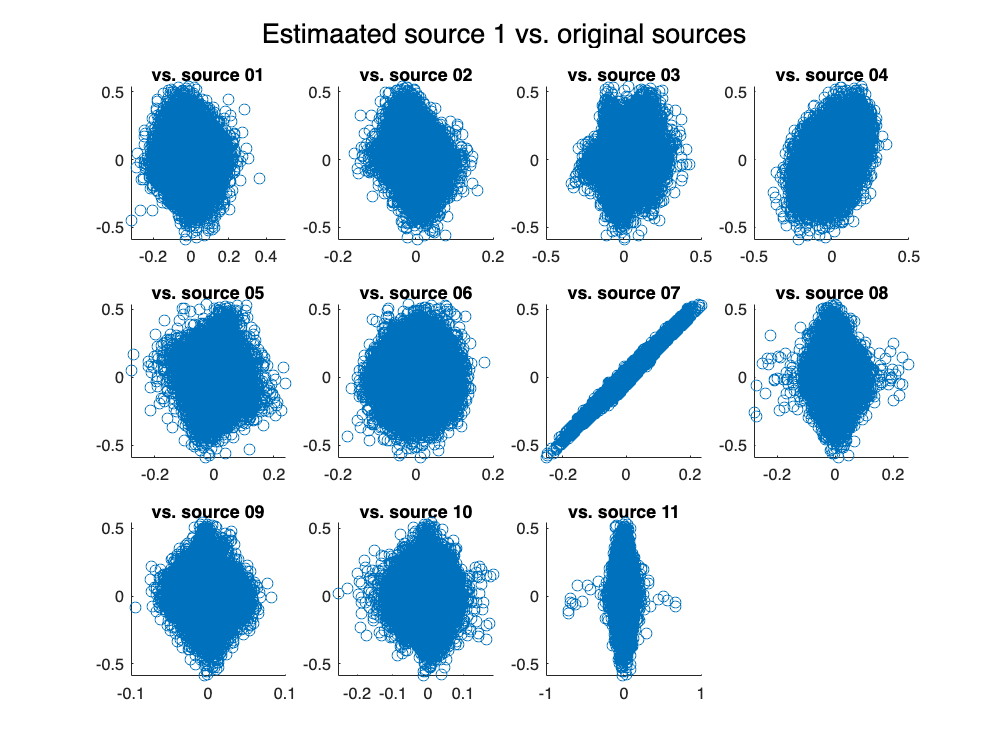

% Check if X_hat is [n_sample x n_ch]

for i=1:size(X_hat, 1)
    fname = sprintf('../data/estimated_source%02d.wav', i);
    audiowrite(fname, X_hat(i, :)', fs);

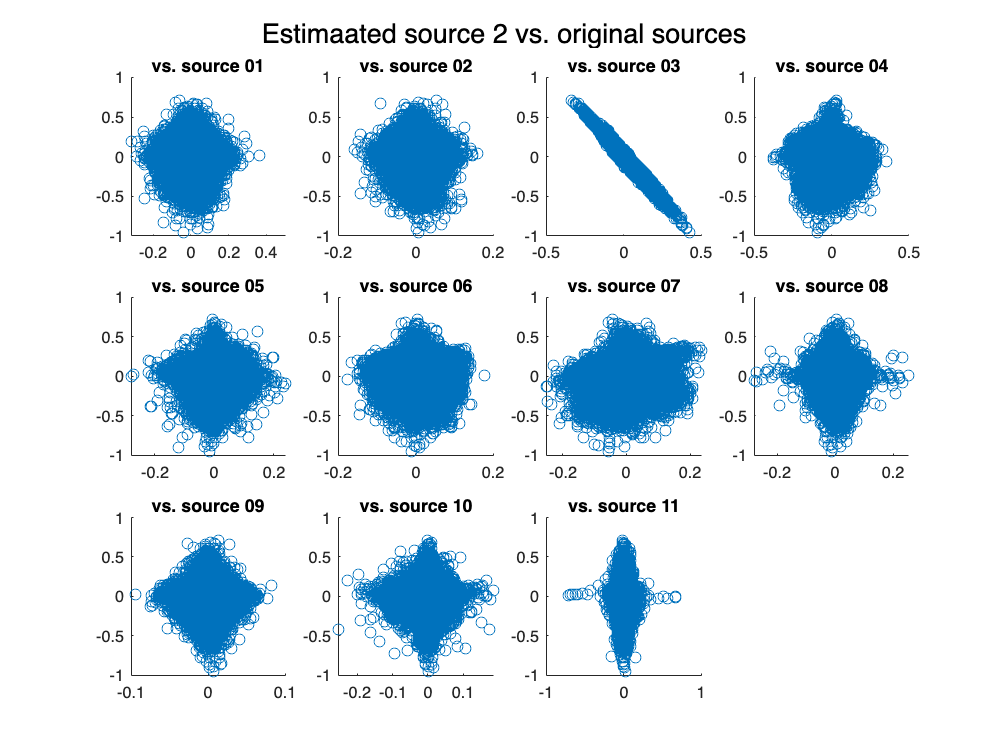

end